# Project 1 3M

Bill Fan + Elvis Wolcott

## Question

How can the societal impacts of public health interventions be limited while remaining within hospital capacity?

Our question is a design question because it attempts to answer how policy makers can craft an intervention that balances multiple concerns. In an ideal world, the only consideration of public health interventions would be reducing the number of cases during an outbreak. In practice, policy makers have to consider the cost of implementation and the economic impact of each intervention. Asking this question will allow us to explore how different elements of a response such as speed of implementation and forecasting distance affect the ability to adequately respond to the virus.

## Model

### SIR+ Model Equations


$$\Delta I_t = \beta \times I_t \times S_t \times (1 - \lambda u)\\
\Delta R_t = \gamma \times I_t \\
\Delta S_t = \alpha \times R_t \\
S_{t+1} = S_t - \Delta I_t + \Delta S_t\\
I_{t+1} = I_t + \Delta I_t - \Delta R_t \\
R_{t+1} = R_t + \Delta R_t - \Delta S_t\\$$



$$\frac{dS}{dt} = -\beta \times I_t \times S_t + \alpha \times R\\
\frac{dI}{dt} = \beta \times I_t \times S_t \times (1 - \lambda u) - \gamma \times I_t \\
\frac{dR}{dt} = \gamma \times I_t - \alpha \times R_t \\$$


### Model with Re-Infection

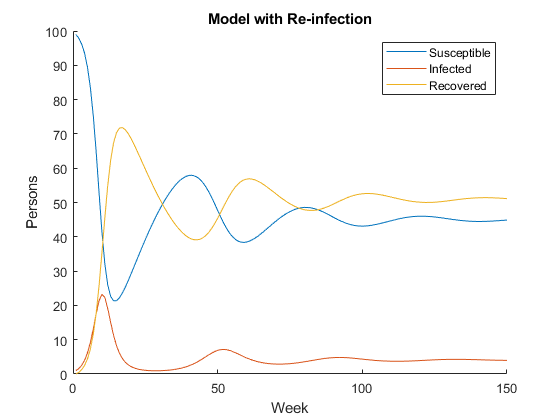

% Initialization
weeks = 150;

s_0 = 99;
i_0 = 1;
r_0 = 0;

beta = 1 / 90;
gamma = 1 / 2;
alpha = 0.04;
% lambda and control are 0 to show base model
lambda = 0;
control = 0;

% Run simulation
[S, I, R, W] = model_simulate(s_0, i_0, r_0, beta, gamma, alpha, lambda, control, weeks);

% Plot
figure(1); clf; hold on;
plot(W, S); label1 = "Susceptible";
plot(W, I); label2 = "Infected";
plot(W, R); label3 = "Recovered";

xlabel("Week")
ylabel("Persons")
legend({label1, label2, label3})
title("Model with Re-infection")

### Verification

Our model should:

- Have a constant total population

- A $\lambda$ of $0$ should **NOT** result in results different from the base model

- A $\lambda$ of $0$ should **NOT **respond to changes to $u$

- An $\alpha$ of $0$ should **NOT **exhibit a second wave

- A $\gamma$ of $0$ should **NOT** show recovery

- A $\beta$ of  $0$ should **NOT **show new infections

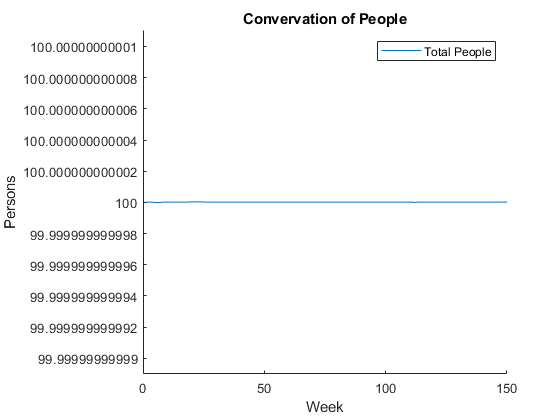

% test: total population is constant
figure(2); clf; hold on;
lambda = 0.5;
threshold = 10;
horizon = 10;
delay = 2;
[S, I, R, U, W] = world_simulate(s_0, i_0, r_0, beta, gamma, alpha, lambda, threshold, horizon, delay, weeks);
plot(W, S + I + R);
label1 = "Total People";
legend({label1});
xlabel("Week")
ylabel("Persons")
title("Convervation of People");

% there's a bit of floating point error - let's see how much
var(S + I + R)

ans = 6.3702e-29

eps(0.5) % according to the docs this should give us a good idea what the error to expect is

ans = 1.1102e-16

There is a slight variance in the total people from week to week, which may be due to floating point rounding errors. Comparing this value to the expected range of floating point error confirms it can reasonably be attributed to floating point error. To the degree possible with floating point operations, the model seems to conserve people. Even if scaled to the entire global population, the floating point error would still be mangitudes less than a single person.

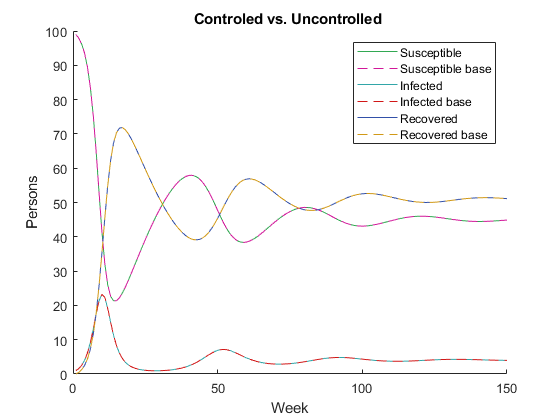

% test: lambda of 0 - same as base model
figure(3); clf; hold on;
lambda = 0;
threshold = 10;
horizon = 10;
delay = 2;
[S_base, I_base, R_base, W_base] = model_simulate(s_0, i_0, r_0, beta, gamma, alpha, lambda, 0, weeks);
[S, I, R, U, W] = world_simulate(s_0, i_0, r_0, beta, gamma, alpha, lambda, threshold, horizon, delay, weeks);
plot(W, S, 'Color', [50, 168, 82]/255); labelS = "Susceptible";
plot(W, S_base, 'Color', [209, 23, 153]/255, 'LineStyle',"--"); labelS_base = "Susceptible base";

plot(W, I, 'Color', [50, 166, 168]/255); labelI = "Infected";
plot(W, I_base, 'Color', [209, 23, 23]/255, 'LineStyle',"--"); labelI_base = "Infected base";

plot(W, R, 'Color', [50, 80, 168]/255); labelR = "Recovered";
plot(W, R_base, 'Color', [209, 153, 23]/255, 'LineStyle',"--"); labelR_base = "Recovered base";

xlabel("Week")
ylabel("Persons")

legend({labelS, labelS_base, labelI, labelI_base, labelR, labelR_base});
title("Controled vs. Uncontrolled ");

As expected, a lambda of 0 (indicating an ineffective control) results in a response identical to the base model.

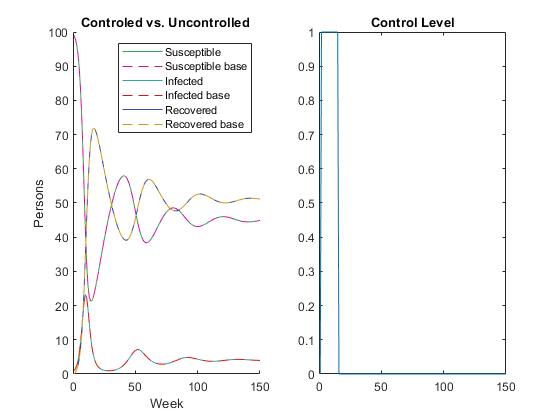

% test: lambda of 0 - doesn't respond to controller
figure(4); clf; hold on;
subplot(1,2,1); hold on;
lambda = 0;
threshold = 10;
horizon = 10;
delay = 2;
[S_base, I_base, R_base, W_base] = model_simulate(s_0, i_0, r_0, beta, gamma, alpha, lambda, 0, weeks);
[S, I, R, U, W] = world_simulate(s_0, i_0, r_0, beta, gamma, alpha, lambda, threshold, horizon, delay, weeks);
plot(W, S, 'Color', [50, 168, 82]/255); labelS = "Susceptible";
plot(W, S_base, 'Color', [209, 23, 153]/255, 'LineStyle',"--"); labelS_base = "Susceptible base";

plot(W, I, 'Color', [50, 166, 168]/255); labelI = "Infected";
plot(W, I_base, 'Color', [209, 23, 23]/255, 'LineStyle',"--"); labelI_base = "Infected base";

plot(W, R, 'Color', [50, 80, 168]/255); labelR = "Recovered";
plot(W, R_base, 'Color', [209, 153, 23]/255, 'LineStyle',"--"); labelR_base = "Recovered base";

xlabel("Week")
ylabel("Persons")

legend({labelS, labelS_base, labelI, labelI_base, labelR, labelR_base});
title("Controled vs. Uncontrolled ");
subplot(1,2,2)
plot(W, U); labelU = "Control";
title("Control Level");

Although a non-zero control value was applied, the controlled model did not deviate from the base model as was expected.

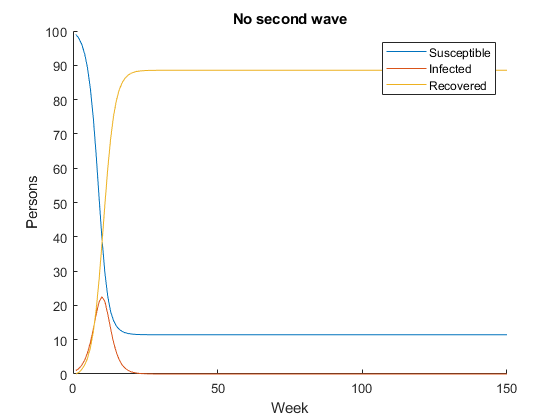

% test: alpha of 0 - shouldn't have a second wave
alpha = 0;
[S, I, R, W] = model_simulate(s_0, i_0, r_0, beta, gamma, alpha, lambda, control, weeks);

% Plot
figure(5); clf; hold on;
plot(W, S); label1 = "Susceptible";
plot(W, I); label2 = "Infected";
plot(W, R); label3 = "Recovered";

xlabel("Week")
ylabel("Persons")
legend({label1, label2, label3})
title("No second wave")

As expected, there is no re-infection.

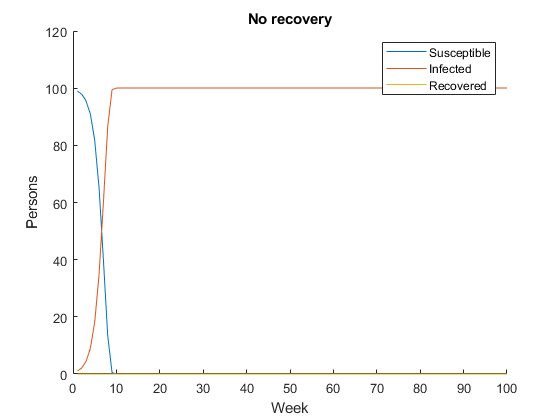

% test: gamma of 0 - shouldn't have recovery
alpha = 0.05;
gamma = 0;
[S, I, R, W] = model_simulate(s_0, i_0, r_0, beta, gamma, alpha, lambda, control, weeks);

% Plot
figure(6); clf; hold on;
plot(W, S); label1 = "Susceptible";
plot(W, I); label2 = "Infected";
plot(W, R); label3 = "Recovered";

xlabel("Week")
ylabel("Persons")
legend({label1, label2, label3})
title("No recovery")

As expected, the infections reach 100 because there is no recovery.

% test: beta of 0 - shouldn't have new infections
beta = 0

beta = 0

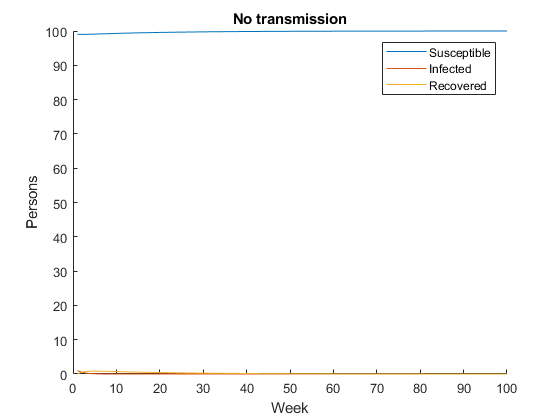

gamma = 1 / 2;
[S, I, R, W] = model_simulate(s_0, i_0, r_0, beta, gamma, alpha, lambda, control, weeks);

% Plot
figure(7); clf; hold on;
plot(W, S); label1 = "Susceptible";
plot(W, I); label2 = "Infected";
plot(W, R); label3 = "Recovered";

xlabel("Week")
ylabel("Persons")
legend({label1, label2, label3})
title("No transmission")

Again, the model performs as expected and there are no new cases.

### Results (Controlled Model)

% Re-initialization
weeks = 100;

s_0 = 99;
i_0 = 1;
r_0 = 0;

beta = 1 / 90;
gamma = 1 / 2;
alpha = 0.04;
lambda =0.5;

threshold = 10;
horizon = 10;
delay = 2;

v_threshold = threshold * (zeros(1, weeks) + 1);

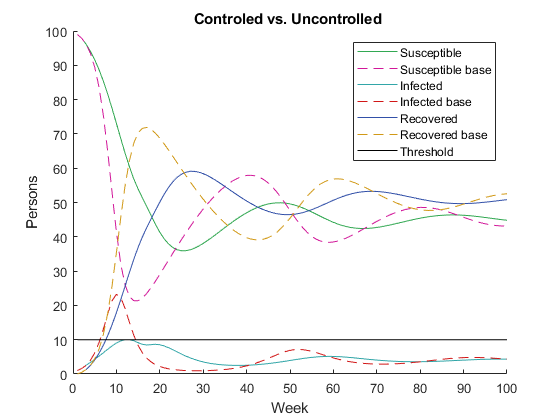

% Run the model given the parameters
[S_base, I_base, R_base, W_base] = model_simulate(s_0, i_0, r_0, beta, gamma, alpha, lambda, 0, weeks);
[S, I, R, U, W] = world_simulate(s_0, i_0, r_0, beta, gamma, alpha, lambda, threshold, horizon, delay, weeks);
% Plot
figure(8); clf; hold on;
plot(W, S, 'Color', [50, 168, 82]/255); labelS = "Susceptible";
plot(W, S_base, 'Color', [209, 23, 153]/255, 'LineStyle',"--"); labelS_base = "Susceptible base";

plot(W, I, 'Color', [50, 166, 168]/255); labelI = "Infected";
plot(W, I_base, 'Color', [209, 23, 23]/255, 'LineStyle',"--"); labelI_base = "Infected base";

plot(W, R, 'Color', [50, 80, 168]/255); labelR = "Recovered";
plot(W, R_base, 'Color', [209, 153, 23]/255, 'LineStyle',"--"); labelR_base = "Recovered base";

plot(W, v_threshold, 'Color', [0, 0, 0]/255); label_threshold = "Threshold";

xlabel("Week")
ylabel("Persons")
% ylim([0, threshold+5])

legend({labelS, labelS_base, labelI, labelI_base, labelR, labelR_base, label_threshold});
title("Controled vs. Uncontrolled ");

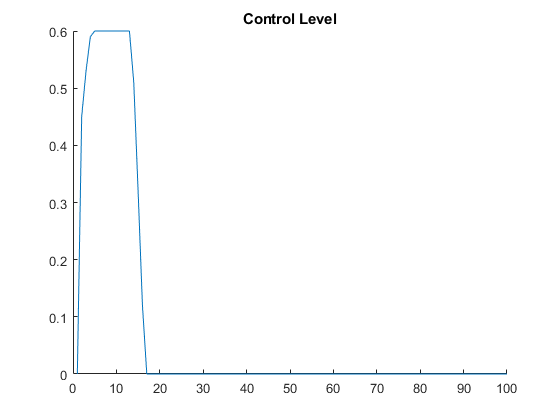

figure(9); clf; hold on;
plot(W, U); labelU = "Control";
title("Control Level");

## Interpretation